clear all; clc; 
format long g;
sensor_data= readmatrix('fort600.xlsx');
sensordata = dlarray(sensor_data);
sensordata = sensordata(1:1597,:);
Data_in = sensordata(1,1:8);
Data_in = [Data_in;sensordata(1,9:16)]

Data_in =   2×8 dlarray

                 4.3119979                0.93504871                 1.2126992                0.14990909                 1.3609625                 1.2958904                 1.4728005                -7.8152902
                 4.6370932                 1.3317006                 1.0280635                0.48291254                0.54450921                 1.7415827                0.65598598                -7.4425119


Data_in = [Data_in; sensordata(1,17:24)]

Data_in =   3×8 dlarray

                 4.3119979                0.93504871                 1.2126992                0.14990909                 1.3609625                 1.2958904                 1.4728005                -7.8152902
                 4.6370932                 1.3317006                 1.0280635                0.48291254                0.54450921                 1.7415827                0.65598598                -7.4425119
                  4.106522                0.83127903                  1.010114                0.15544619                 1.0874505                  1.525336                  1.203144                -7.7867044


for i = 1:1597
    Data_in = [Data_in; sensordata(i,25:32)];
end

Data_out = zeros([8 8 200]);
data = cell(8,1);

for k = 1:8
%     for l =1:200
        Data_out(k,:,:)=Data_in((k-1)*200+1:k*200,:)';
%     end
end

for j =1:8
    data{j} = reshape(Data_out(j,:,:),8,200);
end

% Data_out


## training Parameter

numChannels = 8 ; % no of sensors
numObservations = numel(data);
idxTrain = 1:floor(0.9*numObservations);
idxTest = floor(0.9*numObservations)+1:numObservations;
dataTrain = data(idxTrain);
dataTest = data(idxTest);

for n = 1:numel(dataTrain)
    X = dataTrain{n};
    XTrain{n} = X(:,1:end-1);
    TTrain{n} = X(:,2:end);
end



muX = mean(cat(2,XTrain{:}),2);
sigmaX = std(cat(2,XTrain{:}),0,2);

muT = mean(cat(2,TTrain{:}),2);
sigmaT = std(cat(2,TTrain{:}),0,2);

for n = 1:numel(XTrain)
    XTrain{n} = (XTrain{n} - muX) ./ sigmaX;% standardising the data
    TTrain{n} = (TTrain{n} - muT) ./ sigmaT;% standardising the data
end

## Layer


layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    fullyConnectedLayer(numChannels)
    regressionLayer];

## Train options

options = trainingOptions("adam",MaxEpochs=2000, Verbose=0);
 

options = trainingOptions("adam", ...
    MaxEpochs=1500, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);

## train net

net = trainNetwork(XTrain,TTrain,layers,options);

## Test Network

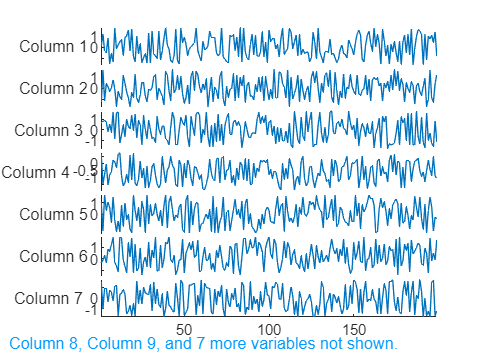

for n = 1:size(dataTest,1)
    X = dataTest{n};
    XTest{n} = (X(:,1:end-1) - muX) ./ sigmaX;
    TTest{n} = (X(:,2:end) - muT) ./ sigmaT;
end

YTest = predict(net,XTest);

stackedplot([XTest{1}',TTest{1}'])

## Ploting prediction on test data

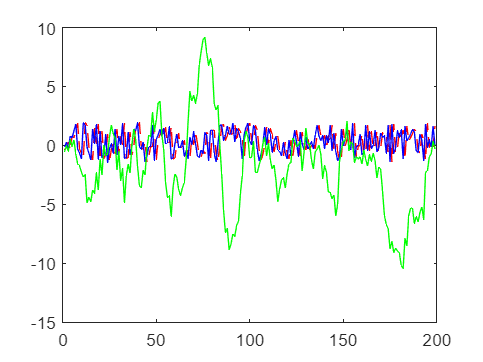

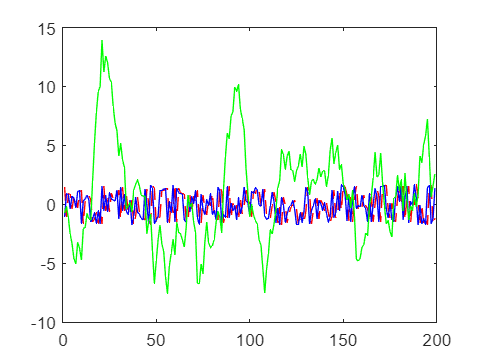

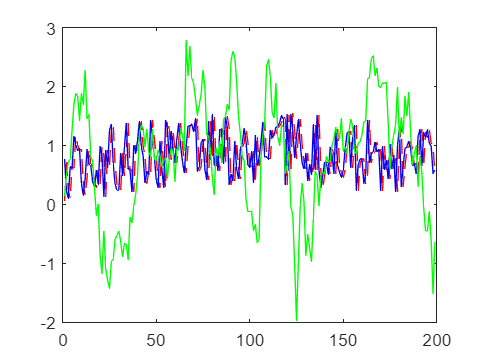

TTest_mat = cell2mat(TTest);% 199x8
XTest_mat = cell2mat(XTest);% 199x8
TTest_mat = TTest_mat';
XTest_mat = XTest_mat';
YTest_mat = cell2mat(YTest);
YTest_mat = YTest_mat';

for k =1:8
    figure(k)
    plot(XTest_mat(:,k),'r--');
    hold on;
    plot(TTest_mat(:,k),'b');
    plot(YTest_mat(:,k),'g');
    hold off;
end